# Trabajo grupal 2 (Métodos Numéricos)

- Sección:

- N° de grupo: 

- Integrante 1 (líder):         

- Integrante 2:

- Integrante 3:

- Integrante 4:

- Integrante 5:

**Observación:** No olvidar añadir el porcentaje de participación.

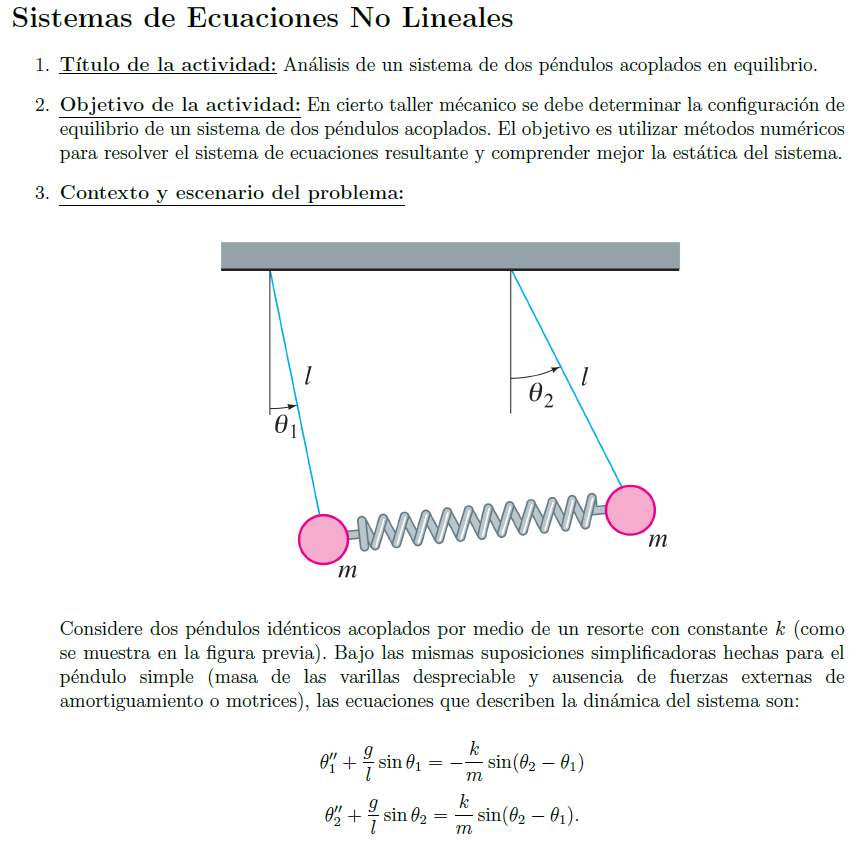

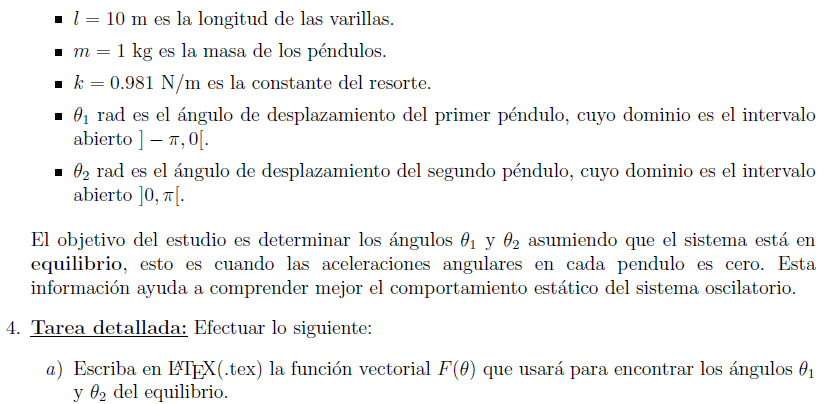

1) Partimos de las ecuaciones originales:


$$\[
\theta_1'' + \frac{g}{l} \sin \theta_1 = -\frac{k}{m} \sin(\theta_2 - \theta_1)
\]
\[
\theta_2'' + \frac{g}{l} \sin \theta_2 = \frac{k}{m} \sin(\theta_2 - \theta_1)
\]$$


2) Establecemos el equilibrio al igualar las segundas derivadas de theta a cero $\left({{\theta_1 }^{\prime } }^{\prime } ,{{\theta_2 }^{\prime } }^{\prime } =0\right)$. Luego, reorganizamos las ecuaciones moviendo todos los términos al lado izquierdo.


$$\[
\frac{g}{l} \sin \theta_1 + \frac{k}{m} \sin(\theta_2 - \theta_1) = 0
\]
\[
\frac{g}{l} \sin \theta_2 - \frac{k}{m} \sin(\theta_2 - \theta_1) = 0
\]$$


3) Lo colocamos en el vector F(theta_1,theta_2)


$$F(\theta_1, \theta_2) = 
\left[ 
\begin{array}{c}
\frac{g}{l} \sin(\theta_1) + \frac{k}{m} \sin(\theta_2 - \theta_1) \\ 
\frac{g}{l} \sin(\theta_2) - \frac{k}{m} \sin(\theta_2 - \theta_1) 
\end{array}
\right]$$


4) Reemplazamos los datos:


$$\[
\frac{g}{l} = 0.981, \quad \frac{k}{m} = 0.981
\]$$



$$F(\theta_1, \theta_2) = 
\left[ 
\begin{array}{c}
0.981 \sin(\theta_1) + 0.981 \sin(\theta_2 - \theta_1) \\ 
0.981 \sin(\theta_2) - 0.981 \sin(\theta_2 - \theta_1) 
\end{array}
\right]$$


5) Factorizamos el 0.981 y nos damos cuenta que como buscamos las raices podemos ignorar dicho numero.


$$F(\theta_1, \theta_2) = 0.981 \left[ 
\matrix{
\sin(\theta_1) + \sin(\theta_2 - \theta_1) \cr 
\sin(\theta_2) - \sin(\theta_2 - \theta_1)
}
\right]

$$


6) Finalmente la funcion vectorial F queda asi:


$$F(\theta_1, \theta_2) = \left[ 
\matrix{
\sin(\theta_1) + \sin(\theta_2 - \theta_1) \cr 
\sin(\theta_2) - \sin(\theta_2 - \theta_1)
}
\right]
$$


% presente sus resultados

% Use el método de Newton y comente sus resultados

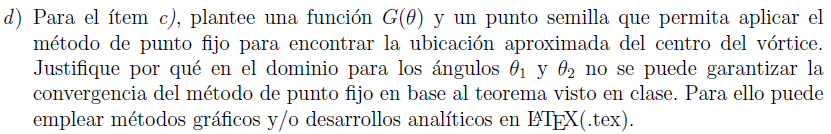

% plantee una función y un punto semilla

% use el método del punto fijo, comente sus resultados

% Realice un comparativo, comente sus resultados.

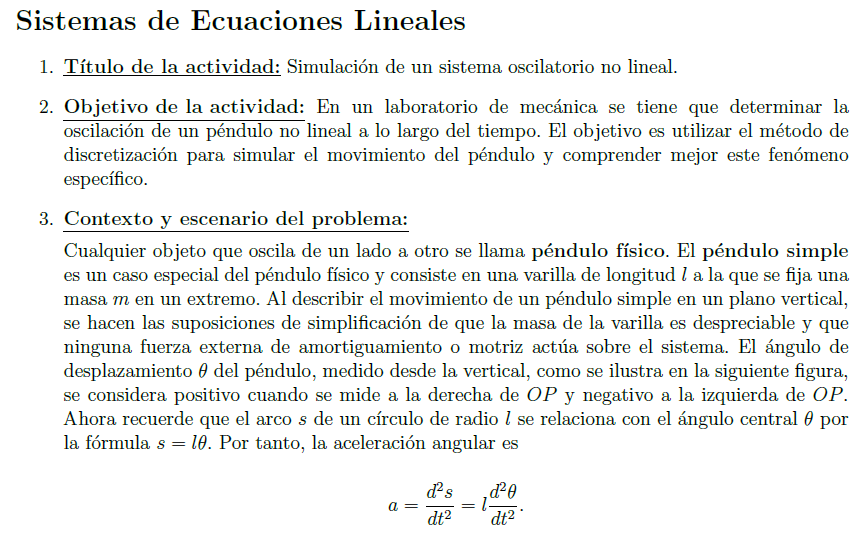

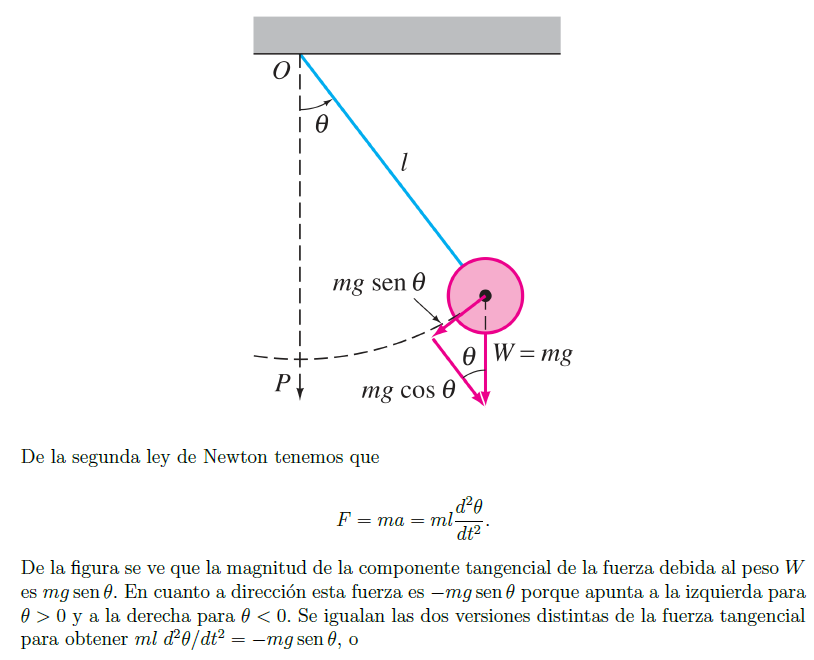

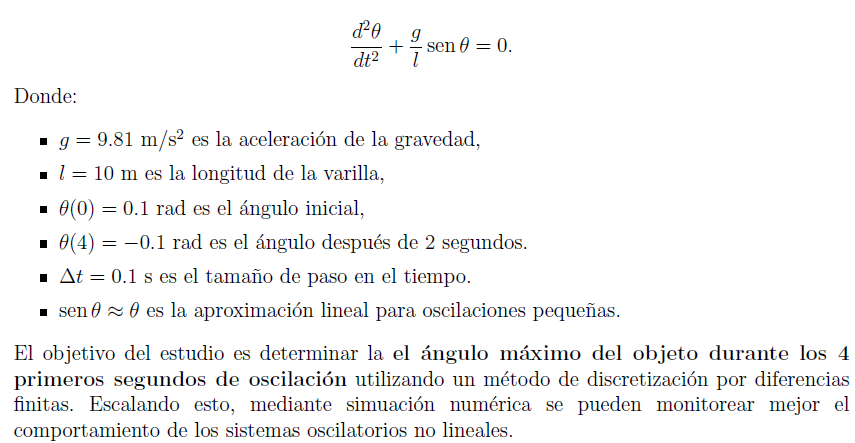

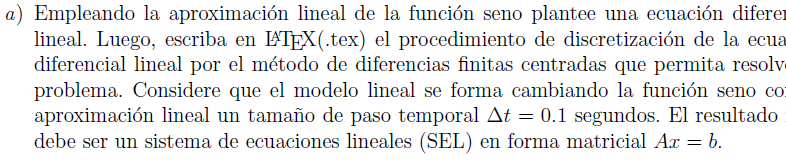

Dada la ecuación diferencial del péndulo simple: $\[
\frac{d^2\theta}{dt^2} + \frac{g}{l} \sin\theta = 0
\]
$

Note que la ecuación anterior es una ecuación diferencial no lineal debido a que se tiene una función sinusoidal en términos de la variable $\theta$. Por tanto, para trabajar con una ecuación lineal, nos apoyamos del dato de que para $\theta$ pequeños se tiene que $\[
\sin\theta \approx \theta
\]
$.

Entonces:         $\[
\frac{d^2\theta}{dt^2} + \frac{g}{l} \theta = 0
\]
$      ...... (I)

Para la discretización de la ecuación (I) se observa que: $\[
\frac{d^2\theta}{dt^2} \approx \frac{\theta_{i+1} - 2\theta_i + \theta_{i-1}}{\Delta t^2}
\]
$     ..... (II)

Luego, reemplazamos la ecuación (II) en (I):


$$\frac{\theta_{i+1} - 2\theta_i + \theta_{i-1}}{\Delta t^2} + \frac{g}{l}\theta = 0$$


Al multiplicar ambos lados por ${\Delta t^2}$, obtenemos: ${\theta_{i+1} - 2\theta_i + \theta_{i-1}} + \frac{g}{l}{\Delta t^2}\theta = 0$   ... (III)

 Reordenamos la ecución (III): ${\theta_{i+1} - (2- \frac{g}{l}{\Delta t^2})\theta_i + \theta_{i-1}}  = 0$

Notamos que los datos de $g
$,$l$ y $\Delta t^2$ son valores conocidos, siendo $\Delta t^2 = \frac{4}{0.1} = 40$, por lo que se tendria el siguiente sistema de ecuaciones


$$\[
\theta_{2} - (2 - 0.0981) \theta_1 + \theta_0 = 0
\]

\[
\theta_{3} - (2 - 0.0981) \theta_2 + \theta_1 = 0
\]

\[
\vdots
\]

\[
\theta_{40} - (2 - 0.0981) \theta_{39} + \theta_{38} = 0
\]
$$


Finalmente, expresamos en formal matricial $A\theta=b$ y los valores ya dados para $g$,$l$ y $\Delta t^2$

% Parámetros del problema
T = 4;                % Tiempo total de simulación (segundos)
dt = 0.1;             % Tamaño de paso temporal (segundos)
g = 9.81;             % Aceleración de la gravedad (m/s^2)
l = 10;               % Longitud de la varilla (m)
N = T/dt - 1;         % Número de pasos de tiempo sin condiciones de frontera
alpha = g/l;          % Coeficiente de la ecuación diferencial

% Construcción del sistema de ecuaciones
A = zeros(N, N);  % Matriz de coeficientes
b = zeros(N, 1);  % Matriz del lado derecho

% Condiciones para B
b(1,1) = -0.1;
b(N,1) = 0.1;

% Construcción de la matriz A
for i = 1:N
    if i > 1
        A(i, i-1) = 1;
    end
    A(i, i) = -2 + (alpha * dt^2);
    if i < N
        A(i, i+1) = 1;
    end
end
A

A =   -1.990190000000000   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
   1.000000000000000  -1.990190000000000   1.000000000000000                   0                   0                   0                   0                   0                   0                   0               

b

b =   -0.100000000000000
                   0
                   0
                   0
                   0
                   0
                   0
                   0
                   0
                   0


fprintf('El ángulo máximo alcanzado es %.5f rad\n', theta_max);

El ángulo máximo alcanzado es 0.10907 rad


**Análisis de convergencia de los métodos iterativos**

#### Para el método de Jacobi

D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
Tj = inv(D)*(L+U);
rhoj = max(abs(eig(Tj)))

rhoj =    1.001831316339775


**Para el método de Gauss Seidel**

D1 = diag(diag(A));
L1 = -tril(A,-1);
U1 = -triu(A,1);
Tgs = inv(D1-L1)*U1;
rhogs = max(abs(eig(Tgs)))

rhogs =    1.003665986399085


% Comparando los radios espectrales
if rhoj < rhogs
    fprintf("El método de Jacobi converge más rápido con %.4f\n", rhoj);
elseif rhogs < rhoj
    fprintf("El método de Gauss-Seidel converge más rápido con %.4f\n", rhogs);
else
    fprintf("Ambos métodos tienen la misma velocidad de convergencia.\n");
end

El método de Jacobi converge más rápido con 1.0018


Dadas los resultados del radio espectral notamos que el método de Gauss Seidel converge más rápido que el método de Jacobi, ya que el primero presenta un rho = 0.9845 mientras que el segundo 0.9922.

% use el método de Jacobi
v_semilla = zeros(39,1);
[erro_jacobi, sol_jacobi]=jacobi(A,b,v_semilla,1e-5);
erro_jacobi

erro_jacobi =      9.995193102584943e-06


sol_jacobi

sol_jacobi =    0.103808438607697
   0.106598516432652
   0.108343536303427
   0.109025706083065
   0.108639614743983
   0.107187768784264
   0.104686174037779
   0.101157607923984
   0.096638758471769
   0.091171882798945


error_jacobi

error_jacobi =      9.995193102584943e-06


v_semilla2 = zeros(39,1);
[error_gauss, sol_gauss]=gausseidel(A,b,v_semilla2,1e-5);
error_gauss

error_gauss =    NaN


sol_gauss

sol_gauss = 1.0e+308 *

   0.136424691569209
   0.272506412755972
   0.407402924338346
   0.540276224024861
   0.670297740821884
   0.796653490158246
   0.918549157764740
   1.035215080629035
   1.145911093866510
   1.249931213061898


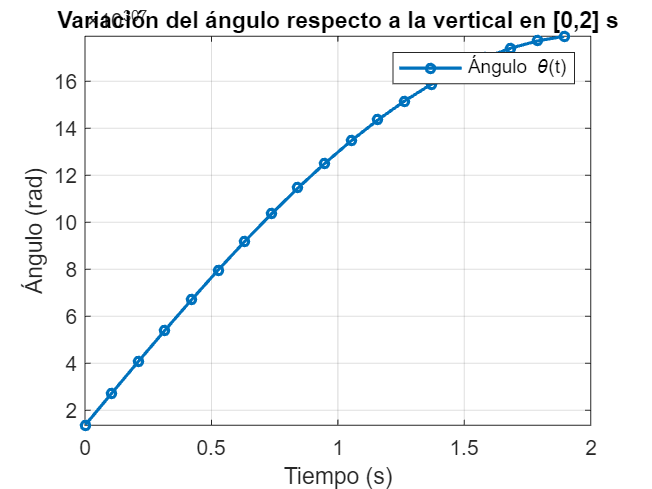

% grafique la variación del ángulo
% Definir el intervalo de tiempo para la gráfica (0 a 2 segundos)
T_plot = 2;
N_plot = T_plot / dt; % Número de pasos de tiempo en [0,2]
t = linspace(0, T_plot, N_plot); % Vector de tiempo

% Extraer los valores correspondientes de la solución
sol_gauss_plot = sol_gauss(1:N_plot);

% Graficar la variación del ángulo
figure;
plot(t, sol_gauss_plot, '-o', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
title('Variación del ángulo respecto a la vertical en [0,2] s');
grid on;
legend('Ángulo \theta(t)');

Ahora se replicará los anteriores items con un tamaño de paso temporal = 0.01

Item a

% Parámetros del problema
TiempoTotal = 4;      % Tiempo total de simulación (segundos)
DeltaT = 0.01;        % Tamaño de paso temporal (segundos)
Gravedad = 9.81;      % Aceleración de la gravedad (m/s^2)
LongitudVarilla = 10; % Longitud de la varilla (m)
NumPasos = TiempoTotal / DeltaT - 1;  % Número de pasos de tiempo sin condiciones de frontera
CoefAlpha = Gravedad / LongitudVarilla;  % Coeficiente de la ecuación diferencial

% Construcción del sistema de ecuaciones
MatrizA = zeros(NumPasos, NumPasos);  % Matriz de coeficientes
VectorB = zeros(NumPasos, 1);  % Matriz del lado derecho

% Condiciones para VectorB
VectorB(1,1) = -0.1;
VectorB(NumPasos,1) = 0.1;

% Construcción de la matriz A
for indice = 1:NumPasos
    if indice > 1
        MatrizA(indice, indice-1) = 1;
    end
    MatrizA(indice, indice) = -2 + (CoefAlpha * DeltaT^2);
    if indice < NumPasos
        MatrizA(indice, indice+1) = 1;
    end
end

MatrizA

MatrizA =   -1.999901900000000   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0          

VectorB

VectorB =   -0.100000000000000
                   0
                   0
                   0
                   0
                   0
                   0
                   0
                   0
                   0


Item b

% Análisis de convergencia de los métodos iterativos
format long
% Para el método de Jacobi
DiagJacobi = diag(diag(MatrizA));
L_Jacobi = -tril(MatrizA, -1);
U_Jacobi = -triu(MatrizA, 1);
T_Jacobi = inv(DiagJacobi) * (L_Jacobi + U_Jacobi);
rho_Jacobi = max(abs(eig(T_Jacobi)))

rho_Jacobi =    1.000018208537919



% Para el método de Gauss-Seidel
DiagGauss = diag(diag(MatrizA));
L_Gauss = -tril(MatrizA, -1);
U_Gauss = -triu(MatrizA, 1);
T_Gauss = inv(DiagGauss - L_Gauss) * U_Gauss;
rho_Gauss = max(abs(eig(T_Gauss)))

rho_Gauss =    1.000036417407384



% Comparando los radios espectrales
if rho_Jacobi < rho_Gauss
    fprintf("El método de Jacobi converge más rápido con %.15f\n", rho_Jacobi);
elseif rho_Gauss < rho_Jacobi
    fprintf("El método de Gauss-Seidel converge más rápido con %.15f\n", rho_Gauss);
else
    fprintf("Ambos métodos tienen la misma velocidad de convergencia.\n");
end

El método de Jacobi converge más rápido con 1.000018208537919


Dadas los resultados del radio espectral notamos que, el método de Jacobi converge más rápido con un valor de rho 1.000018208537919

Item c

% use el método de Jacobi
v_semilla_ = zeros(399,1);
[erro_jacobi_, sol_jacobi_]=jacobi(MatrizA,VectorB,v_semilla_,1e-5);
erro_jacobi_

erro_jacobi_ =      9.999731667990269e-06


sol_jacobi_

sol_jacobi_ =    0.100314590015450
   0.100619339169620
   0.100914283629027
   0.101199328397210
   0.101474577570902
   0.101739872088533
   0.101995383851221
   0.102240889866753
   0.102476629649048
   0.102702316473975


Item d

v_semilla2_ = zeros(399,1);
[error_gauss_, sol_gauss_]=gausseidel(MatrizA,VectorB,v_semilla2_,1e-5);
error_gauss_

error_gauss_ =      9.998567664830527e-06


sol_gauss_

sol_gauss_ =    0.100329449034546
   0.100649088792241
   0.100958904423933
   0.101258882029863
   0.101549008657054
   0.101829272296592
   0.102099661880838
   0.102360167280545
   0.102610779301890
   0.102851489683431


Item e

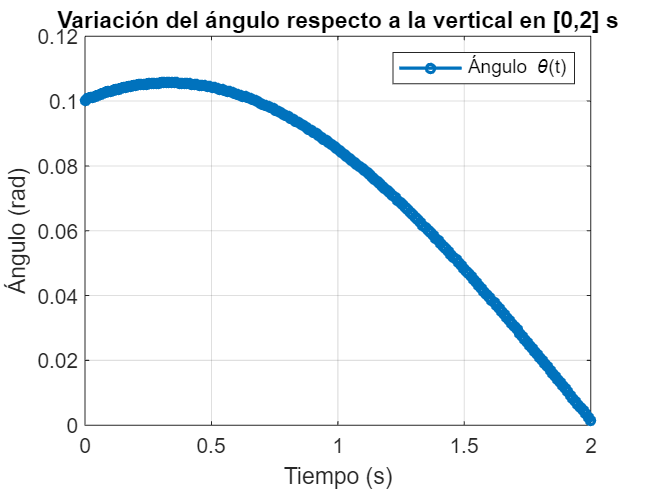

% Método de Gauss-Seidel
VectorInicial = zeros(NumPasos,1);
[ErrorGauss, SolGauss] = gausseidel(MatrizA, VectorB, VectorInicial, 1e-5);

% Definir el intervalo de tiempo para la gráfica (0 a 2 segundos)
TiempoGrafica = 2;
NumPasosGraf = TiempoGrafica / DeltaT; % Número de pasos de tiempo en [0,2]
TiempoVec = linspace(0, TiempoGrafica, NumPasosGraf); % Vector de tiempo

% Extraer los valores correspondientes de la solución
SolGaussGraf = SolGauss(1:NumPasosGraf);

% Graficar la variación del ángulo
figure;
plot(TiempoVec, SolGaussGraf, '-o', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
title('Variación del ángulo respecto a la vertical en [0,2] s');
grid on;
legend('Ángulo \theta(t)');

## Funciones:

% en esta sección van las funciones usadas

function [error,x1]=jacobi(A,b,x0,Tol)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    Tj=inv(D)*(L+U);
    %rho=max(abs(eig(Tj))); %eig calcula los valores propios
    cj=inv(D)*b;
    error=1;
    %z=[x0' error];
    while error>Tol %mientras que el error sea > que la tolerancia
        x1=Tj*x0+cj;
        error=norm(x1-x0,inf)/norm(x1,inf); %norma infinita
        %z=[z;x1' error];
        x0=x1;
    end
end

function [error, x1]=gausseidel(A,b,x0,Tol)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    Tgs=inv(D-L)*U;
    %rho=max(abs(eig(Tgs))) %eig calcula los valores propios
    cgs=inv(D-L)*b;
    error=1;
    %z=[x0' error];
    while error>Tol
        x1=Tgs*x0+cgs;
        error=norm(x1-x0,inf)/norm(x1,inf);
        %z=[z;x1' error];
        x0=x1;
    end
end